### Risoluzione letterale

clear
clc

syms t; % tempo
syms T; % energia cinetica del sistema
syms U; % energia potenziale del sistema
syms alpha; % Angolo di offset statico che sposta in avanti il baricentro
syms beta; % Altro angolo statico, vedi disegno
syms l_c l_a l_b m_a m_c m_r m_b J_r J_b J_a J_c g r;
syms q_1 q_1_p q_2 q_2_p;
syms b; % Attrito viscoso
% Coordinate libere
syms phi(t); % Angolo letto dagli encoder
vel = diff(phi, t); %velocità carello
syms theta(t); % angolo inclinazione
vel_ang = diff(theta, t);%vel angolare
syms q_1 q_1_p q_2 q_2_p;

### Definisco il problema per il punto Pa

P_a = [phi*r+l_a*sin(theta+beta); l_a*cos(theta+beta); theta]

$$P\_a(t) = \left(\begin{array}{c} r\,\varphi \left(t\right)+l_{a}\,\sin\left(\beta +\theta \left(t\right)\right)\\ l_{a}\,\cos\left(\beta +\theta \left(t\right)\right)\\ \theta \left(t\right) \end{array}\right)$$

V_a = diff(P_a, t)

$$V\_a(t) = \left(\begin{array}{c} r\,\frac{\partial }{\partial t}\varphi \left(t\right)+l_{a}\,\cos\left(\beta +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ -l_{a}\,\sin\left(\beta +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_a = [m_a,0,0; 0,m_a,0; 0,0,J_a] % Matrice delle masse/inerzie

$$M\_a = \left(\begin{array}{ccc} m_{a} & 0 & 0\\ 0 & m_{a} & 0\\ 0 & 0 & J_{a} \end{array}\right)$$

T_a = 1/2 * transpose(V_a) * M_a * V_a;
U_a = m_a * g * l_a * cos(theta+beta);
L_a = T_a - U_a

$$L\_a(t) = \begin{array}{l} \frac{J_{a}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+m_{a}\,\left(r\,\frac{\partial }{\partial t}\varphi \left(t\right)+\sigma_{1}\right)\,\left(\frac{r\,\frac{\partial }{\partial t}\varphi \left(t\right)}{2}+\frac{\sigma_{1}}{2}\right)+\frac{{l_{a}}^{2}\,m_{a}\,{\sin\left(\beta +\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}-g\,l_{a}\,m_{a}\,\cos\left(\beta +\theta \left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=l_{a}\,\cos\left(\beta +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}$$

### Definisco il problema per il punto Pc (utente)

P_c = [phi*r+l_c*sin(theta+alpha); l_c*cos(theta+alpha); theta + alpha]

$$P\_c(t) = \left(\begin{array}{c} r\,\varphi \left(t\right)+l_{c}\,\sin\left(\alpha +\theta \left(t\right)\right)\\ l_{c}\,\cos\left(\alpha +\theta \left(t\right)\right)\\ \alpha +\theta \left(t\right) \end{array}\right)$$

V_c = diff(P_c,t)

$$V\_c(t) = \left(\begin{array}{c} r\,\frac{\partial }{\partial t}\varphi \left(t\right)+l_{c}\,\cos\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ -l_{c}\,\sin\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_c = [m_c,0,0; 0,m_c,0; 0,0,J_c]

$$M\_c = \left(\begin{array}{ccc} m_{c} & 0 & 0\\ 0 & m_{c} & 0\\ 0 & 0 & J_{c} \end{array}\right)$$

T_c = 1/2 * transpose(V_c) * M_c * V_c;
U_c = m_c * g * l_c * cos(alpha+theta);
L_c = T_c - U_c

$$L\_c(t) = \begin{array}{l} \frac{J_{c}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+m_{c}\,\left(r\,\frac{\partial }{\partial t}\varphi \left(t\right)+\sigma_{1}\right)\,\left(\frac{r\,\frac{\partial }{\partial t}\varphi \left(t\right)}{2}+\frac{\sigma_{1}}{2}\right)+\frac{{l_{c}}^{2}\,m_{c}\,{\sin\left(\alpha +\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}-g\,l_{c}\,m_{c}\,\cos\left(\alpha +\theta \left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=l_{c}\,\cos\left(\alpha +\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}$$

### Definisco il problema per il punto Pb (base)

P_b = [phi*r+l_b*sin(pi+theta); l_b*cos(pi+theta); pi+theta]

$$P\_b(t) = \left(\begin{array}{c} r\,\varphi \left(t\right)-l_{b}\,\sin\left(\theta \left(t\right)\right)\\ -l_{b}\,\cos\left(\theta \left(t\right)\right)\\ \pi +\theta \left(t\right) \end{array}\right)$$

V_b = diff(P_b,t)

$$V\_b(t) = \left(\begin{array}{c} r\,\frac{\partial }{\partial t}\varphi \left(t\right)-l_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ l_{b}\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

M_b = [m_b,0,0; 0,m_b,0; 0,0,J_b]

$$M\_b = \left(\begin{array}{ccc} m_{b} & 0 & 0\\ 0 & m_{b} & 0\\ 0 & 0 & J_{b} \end{array}\right)$$

T_b = 1/2 * transpose(V_b) * M_b * V_b;
U_b = m_b * g * l_b * cos(pi+theta);
L_b = T_b - U_b

$$L\_b(t) = \begin{array}{l} \frac{J_{b}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+m_{b}\,\left(r\,\frac{\partial }{\partial t}\varphi \left(t\right)-\sigma_{1}\right)\,\left(\frac{r\,\frac{\partial }{\partial t}\varphi \left(t\right)}{2}-\frac{\sigma_{1}}{2}\right)+\frac{{l_{b}}^{2}\,m_{b}\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}}{2}+g\,l_{b}\,m_{b}\,\cos\left(\theta \left(t\right)\right)\\ \mathrm{where}\\ \sigma_{1}=l_{b}\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right) \end{array}$$

### Definisco il problema per il punto Pr (ruota)

P_r = [phi*r; 0; phi]

$$P\_r(t) = \left(\begin{array}{c} r\,\varphi \left(t\right)\\ 0\\ \varphi \left(t\right) \end{array}\right)$$

V_r = diff(P_r,t)

$$V\_r(t) = \left(\begin{array}{c} r\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ 0\\ \frac{\partial }{\partial t}\varphi \left(t\right) \end{array}\right)$$

M_r = [m_r,0,0; 0,m_r,0; 0,0,J_r]

$$M\_r = \left(\begin{array}{ccc} m_{r} & 0 & 0\\ 0 & m_{r} & 0\\ 0 & 0 & J_{r} \end{array}\right)$$

T_r = 1/2 * transpose(V_r) * M_r * V_r;
U_r = 0;
L_r = T_r - U_r

$$L\_r(t) = \frac{m_{r}\,r^{2}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}+\frac{J_{r}\,{\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}}{2}$$

### Lagrangiana del sistema

L = collect(simplify(2*L_r + L_a + L_b + L_c))
L_q = subs(L,{phi,vel,theta,vel_ang},{q_1 q_1_p q_2 q_2_p}); % Esprimo la Lagrangiana rispetto ai simboli di coordinate libere generiche (q_1 etc)

### Calcolo equazioni del moto rispetto a q_1 (phi)

dL_dq1 = diff(L_q,q_1);
dL_dphi = subs(dL_dq1,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq1p = diff(L_q,q_1_p);
dL_dvel = subs(dL_dq1p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_dt = diff(dL_dvel,t);

E_L_phi = collect(simplify(dL_dvel_dt - dL_dphi == F))

### Calcolo equazioni del moto rispetto a q_2 (theta)

dL_dq2 = diff(L_q,q_2);
dL_dtheta = subs(dL_dq2,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});

dL_dq2p = diff(L_q,q_2_p);
dL_dvel_ang = subs(dL_dq2p,{q_1 q_1_p q_2 q_2_p},{phi,vel,theta,vel_ang});
dL_dvel_ang_dt = diff(dL_dvel_ang,t);

E_L_theta = collect(dL_dvel_ang_dt - dL_dtheta == - b * vel* r)

$$L(t) = \begin{array}{l} J_{r}\,\sigma_{2}+\frac{J_{a}\,\sigma_{1}}{2}+\frac{J_{b}\,\sigma_{1}}{2}+\frac{J_{c}\,\sigma_{1}}{2}+\frac{{l_{a}}^{2}\,m_{a}\,\sigma_{1}}{2}+\frac{{l_{b}}^{2}\,m_{b}\,\sigma_{1}}{2}+\frac{{l_{c}}^{2}\,m_{c}\,\sigma_{1}}{2}+\frac{m_{a}\,r^{2}\,\sigma_{2}}{2}+\frac{m_{b}\,r^{2}\,\sigma_{2}}{2}+\frac{m_{c}\,r^{2}\,\sigma_{2}}{2}+m_{r}\,r^{2}\,\sigma_{2}-g\,l_{c}\,m_{c}\,\sigma_{4}-g\,l_{a}\,m_{a}\,\sigma_{3}+g\,l_{b}\,m_{b}\,\cos\left(\theta \left(t\right)\right)+l_{c}\,m_{c}\,r\,\sigma_{4}\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)+l_{a}\,m_{a}\,r\,\sigma_{3}\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)-l_{b}\,m_{b}\,r\,\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\,\frac{\partial }{\partial t}\varphi \left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\varphi \left(t\right)\right)}^{2}\\ \sigma_{3}=\cos\left(\beta +\theta \left(t\right)\right)\\ \sigma_{4}=\cos\left(\alpha +\theta \left(t\right)\right) \end{array}$$

$$E\_L\_theta(t) = \begin{array}{l} J_{a}\,\sigma_{1}+J_{b}\,\sigma_{1}+J_{c}\,\sigma_{1}+{l_{a}}^{2}\,m_{a}\,\sigma_{1}+{l_{b}}^{2}\,m_{b}\,\sigma_{1}+{l_{c}}^{2}\,m_{c}\,\sigma_{1}-g\,l_{c}\,m_{c}\,\sin\left(\alpha +\theta \left(t\right)\right)-g\,l_{a}\,m_{a}\,\sin\left(\beta +\theta \left(t\right)\right)+g\,l_{b}\,m_{b}\,\sin\left(\theta \left(t\right)\right)-l_{b}\,m_{b}\,r\,\cos\left(\theta \left(t\right)\right)\,\sigma_{2}+l_{c}\,m_{c}\,r\,\cos\left(\alpha +\theta \left(t\right)\right)\,\sigma_{2}+l_{a}\,m_{a}\,r\,\cos\left(\beta +\theta \left(t\right)\right)\,\sigma_{2}=0\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right) \end{array}$$

$$E\_L\_phi(t) = \begin{array}{l} 2\,J_{r}\,\sigma_{1}+m_{a}\,r^{2}\,\sigma_{1}+m_{b}\,r^{2}\,\sigma_{1}+m_{c}\,r^{2}\,\sigma_{1}+2\,m_{r}\,r^{2}\,\sigma_{1}+l_{b}\,m_{b}\,r\,\sin\left(\theta \left(t\right)\right)\,\sigma_{2}-l_{b}\,m_{b}\,r\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}-l_{c}\,m_{c}\,r\,\sin\left(\alpha +\theta \left(t\right)\right)\,\sigma_{2}-l_{a}\,m_{a}\,r\,\sin\left(\beta +\theta \left(t\right)\right)\,\sigma_{2}+l_{c}\,m_{c}\,r\,\cos\left(\alpha +\theta \left(t\right)\right)\,\sigma_{3}+l_{a}\,m_{a}\,r\,\cos\left(\beta +\theta \left(t\right)\right)\,\sigma_{3}=F\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}$$

### Risoluzione delle equazioni del moto

syms q1_s q2_s; % Derivate seconde delle coordinate libere
acc_ang = diff(theta, t, 2);
acc = diff(phi, t, 2);

eqns = [subs(E_L_theta, {acc,acc_ang},{q1_s,q2_s}), subs(E_L_phi, {acc,acc_ang},{q1_s,q2_s})];
[theta2, phi2] = solve(eqns, [q1_s q2_s]);

Linearizzazione intorno all'equilibrio [0,0,0,0], uso la matrice A come

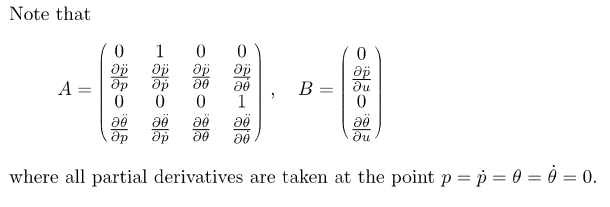

syms u;
theta2_differenziabile = subs(theta2,{phi,vel,theta,vel_ang,F},{q_1 q_1_p q_2 q_2_p u});
phi2_differenziabile = subs(phi2,{phi,vel,theta,vel_ang,F},{q_1 q_1_p q_2 q_2_p u});

%phi, phi_primo, theta, theta_primo, F (u = INPUT)
equilibrio = {0,0,0,0,0};

A11 = 0;
A12 = 1;
A13 = 0;
A14 = 0;
A21 = subs(diff(phi2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A22 = subs(diff(phi2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A23 = subs(diff(phi2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A24 = subs(diff(phi2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A31 = 0;
A32 = 0;
A33 = 0;
A34 = 1;
A41 = subs(diff(theta2_differenziabile,q_1),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A42 = subs(diff(theta2_differenziabile,q_1_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A43 = subs(diff(theta2_differenziabile,q_2),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A44 = subs(diff(theta2_differenziabile,q_2_p),{q_1 q_1_p q_2 q_2_p u},equilibrio);
A = [A11 A12 A13 A14;A21 A22 A23 A24;A31 A32 A33 A34; A41 A42 A43 A44]

B11 = 0;
B21 = subs(diff(phi2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B31 = 0;
B41 = subs(diff(theta2_differenziabile,u),{q_1 q_1_p q_2 q_2_p u},equilibrio);
B = [B11;B21;B31;B41]

% Uscita l'angolo
% C -> matrice [2 (2 output) x 4 (4 var di stato)] TODO --> spiegazione
C = [0,0,1,0]
D = 0

syms s G(s);

equilibrio = 1×5 cell array
    {[0]}    {[0]}    {[0]}    {[0]}    {[0]}


C =      0     0     1     0


temp_1 = collect(simplify(s *eye(4)));

temp_2 = collect(simplify(temp_1 - A));

temp_3 = collect(simplify((temp_2)^-1)); % calcolo molto pesante

temp_4 = collect(simplify(temp_3 * B));

G = collect(simplify(C * temp_4 + D));